%% Initialization
clear ; close all; clc

fprintf('Finding closest centroids.\n\n');

Finding closest centroids.



tableQBs = readtable('2021QBs.csv');

%Standard tiering
QBs = tableQBs(1:31,:);
QBs_TOTYDSandTOTTDS = table2array(QBs(:,[20 19]))

QBs_TOTYDSandTOTTDS =         6268          40
        5534          38
        5233          42
        5550          37
        4259          38
        4965          36
        4777          38
        5490          26
        4592          33
        4711          28


% Select an initial set of centroids
K_1 = 6; % 6 Centroids
max_iters_1 = 4;
initial_QBs_TOTYDSvTOTTDS_centroids = [6000 40; 5250 35; 4500 30; 3500 25; 3000 20; 2500 15];

idx_1 = findClosestCentroids(QBs_TOTYDSandTOTTDS,initial_QBs_TOTYDSvTOTTDS_centroids);
QBs_TOTYDSvTOTTDS_centroids = computeCentroids(QBs_TOTYDSandTOTTDS, idx_1, K_1)

QBs_TOTYDSvTOTTDS_centroids = 	1.0e+03 *

    6.2680    0.0400
    5.2714    0.0311
    4.3879    0.0280
    3.5396    0.0194
    2.9533    0.0130
    2.5945    0.0125


K-Means iteration 1/4...


K-Means iteration 2/4...


K-Means iteration 3/4...


K-Means iteration 4/4...


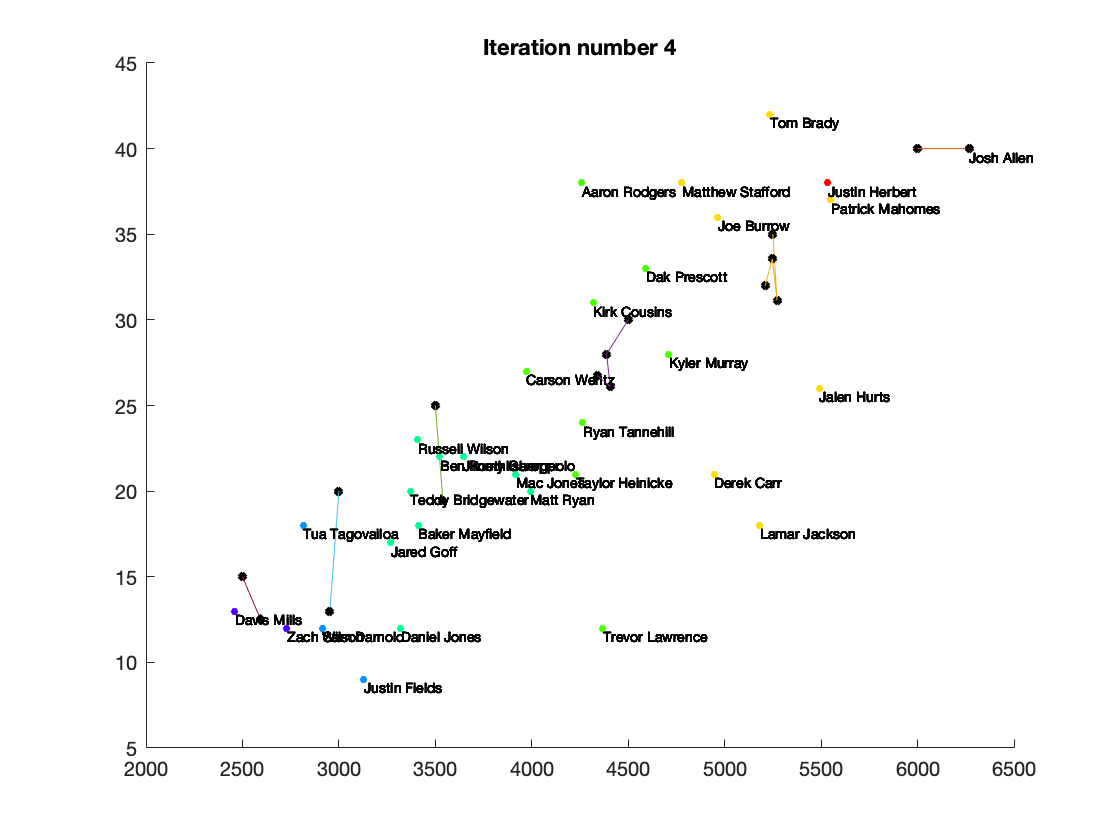

[QBs_TOTYDSvTOTTDS_centroids, idx_1] = runkMeans(QBs_TOTYDSandTOTTDS, initial_QBs_TOTYDSvTOTTDS_centroids, max_iters_1, true);

function idx = findClosestCentroids(X, centroids)
%FINDCLOSESTCENTROIDS computes the centroid memberships for every example
%   idx = FINDCLOSESTCENTROIDS (X, centroids) returns the closest centroids
%   in idx for a dataset X where each row is a single example. idx = m x 1 
%   vector of centroid assignments (i.e. each entry in range [1..K])
%

K = size(centroids, 1);

idx = zeros(size(X,1), 1);

for i = 1:size(X,1)
    distance = 99999;
    for j = 1:K
        distance_current = norm(X(i,:)-centroids(j,:))^2;
        if distance_current < distance
            temp_j = j;
            distance = distance_current;
        end
    end
    idx(i) = temp_j;
end





% =============================================================

end


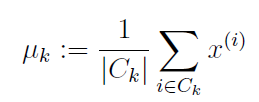

function centroids = computeCentroids(X, idx, K)
%COMPUTECENTROIDS returns the new centroids by computing the means of the 
%data points assigned to each centroid.
%   centroids = COMPUTECENTROIDS(X, idx, K) returns the new centroids by 
%   computing the means of the data points assigned to each centroid. It is
%   given a dataset X where each row is a single data point, a vector
%   idx of centroid assignments (i.e. each entry in range [1..K]) for each
%   example, and K, the number of centroids. You should return a matrix
%   centroids, where each row of centroids is the mean of the data points
%   assigned to it.
%

[m n] = size(X);

centroids = zeros(K, n);


for k = 1:K
    subset = X(idx==k,:);
    centroids(k,:) = mean(subset,1);
end







% =============================================================


end

function centroids = kMeansInitCentroids(X, K)
%KMEANSINITCENTROIDS This function initializes K centroids that are to be 
%used in K-Means on the dataset X
%   centroids = KMEANSINITCENTROIDS(X, K) returns K initial centroids to be
%   used with the K-Means on the dataset X
% 

centroids = zeros(K, size(X, 2));


ind = randperm(size(X,1));
centroids = X(ind(1:K),:);







% =============================================================

end



Appendix

function [centroids, idx] = runkMeans(X, initial_centroids, ...
                                      max_iters, plot_progress)
%RUNKMEANS runs the K-Means algorithm on data matrix X, where each row of X
%is a single example
%   [centroids, idx] = RUNKMEANS(X, initial_centroids, max_iters, ...
%   plot_progress) runs the K-Means algorithm on data matrix X, where each 
%   row of X is a single example. It uses initial_centroids used as the
%   initial centroids. max_iters specifies the total number of interactions 
%   of K-Means to execute. plot_progress is a true/false flag that 
%   indicates if the function should also plot its progress as the 
%   learning happens. This is set to false by default. runkMeans returns 
%   centroids, a Kxn matrix of the computed centroids and idx, a m x 1 
%   vector of centroid assignments (i.e. each entry in range [1..K])
%

% Set default value for plot progress
if ~exist('plot_progress', 'var') || isempty(plot_progress)
    plot_progress = false;
end

% Plot the data if we are plotting progress
if plot_progress
    figure;
    hold on;
end

% Initialize values
[m n] = size(X);
K = size(initial_centroids, 1);
centroids = initial_centroids;
previous_centroids = centroids;
idx = zeros(m, 1);

% Run K-Means
for i=1:max_iters
    
    % Output progress
    fprintf('K-Means iteration %d/%d...\n', i, max_iters);
    if exist('OCTAVE_VERSION')
        fflush(stdout);
    end
    
    % For each example in X, assign it to the closest centroid
    idx = findClosestCentroids(X, centroids);
    
    % Optionally, plot progress here
    if plot_progress
        plotProgresskMeans(X, centroids, previous_centroids, idx, K, i);
        previous_centroids = centroids;
        %fprintf('Press enter to continue.\n');
        %pause;
    end
    
    % Given the memberships, compute new centroids
    centroids = computeCentroids(X, idx, K);
end

% Hold off if we are plotting progress
if plot_progress
    hold off;
end

end

function plotProgresskMeans(X, centroids, previous, idx, K, i)
%PLOTPROGRESSKMEANS is a helper function that displays the progress of 
%k-Means as it is running. It is intended for use only with 2D data.
%   PLOTPROGRESSKMEANS(X, centroids, previous, idx, K, i) plots the data
%   points with colors assigned to each centroid. With the previous
%   centroids, it also plots a line between the previous locations and
%   current locations of the centroids.
%

% Plot the examples
plotDataPoints(X, idx, K);
tableQBs = readtable('2021QBs.csv');
QBs = tableQBs(1:31,:);
QBnames = table2cell(QBs(:,1));
text(X(:,1),X(:,2),QBnames,'VerticalAlignment','top','HorizontalAlignment','left','FontSize',7);
%xpos = X(:,1);
%ypos = X(:,2);
%labels = TEnames;
%h = labelpoints (xpos, ypos, labels);

% Plot the centroids as black x's
plot(centroids(:,1), centroids(:,2), 'x', ...
     'MarkerEdgeColor','k', ...
     'MarkerSize', 2, 'LineWidth', 3);

% Plot the history of the centroids with lines
for j=1:size(centroids,1)
    drawLine(centroids(j, :), previous(j, :));
end

% Title
title(sprintf('Iteration number %d', i))

end
function plotDataPoints(X, idx, K)
%PLOTDATAPOINTS plots data points in X, coloring them so that those with the same
%index assignments in idx have the same color
%   PLOTDATAPOINTS(X, idx, K) plots data points in X, coloring them so that those 
%   with the same index assignments in idx have the same color

% Create palette
palette = hsv(K + 1);
colors = palette(idx, :);

% Plot the data
scatter(X(:,1), X(:,2), 15, colors,'filled');
tableQBs = readtable('2021QBs.csv');
QBs = tableQBs(1:31,:);
QBnames = table2cell(QBs(:,1));
text(X(:,1),X(:,2),QBnames,'VerticalAlignment','top','HorizontalAlignment','left','FontSize',7);
end

function drawLine(p1, p2, varargin)
%DRAWLINE Draws a line from point p1 to point p2
%   DRAWLINE(p1, p2) Draws a line from point p1 to point p2 and holds the
%   current figure

plot([p1(1) p2(1)], [p1(2) p2(2)], varargin{:});

end